## question 1

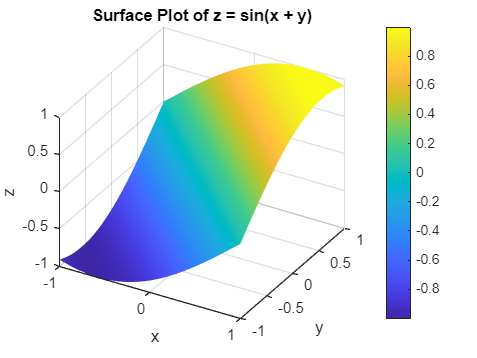


x = linspace(-1, 1, 100);
y = linspace(-1, 1, 100);
[X, Y] = meshgrid(x, y);


Z = sin(X + Y);


figure;
surf(X, Y, Z, 'EdgeColor', 'none'); 
colormap('parula'); 
colorbar; 
shading interp; 

xlabel('x');
ylabel('y');
zlabel('z');
title('Surface Plot of z = sin(x + y)');


view(30, 35); 

## question 2

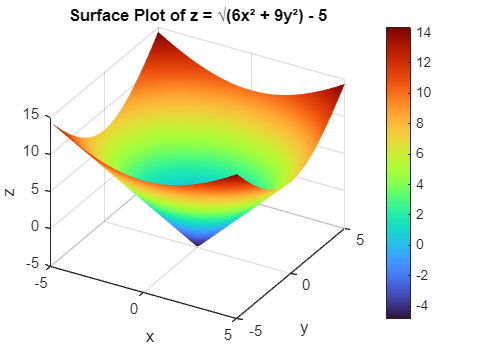

x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);

Z = sqrt(6*X.^2 + 9*Y.^2) - 5;

figure;
surf(X, Y, Z, 'EdgeColor', 'none');
colormap('turbo');
colorbar;
shading interp;

xlabel('x');
ylabel('y');
zlabel('z');
title('Surface Plot of z = √(6x² + 9y²) - 5');
view(30, 35);

## question 3

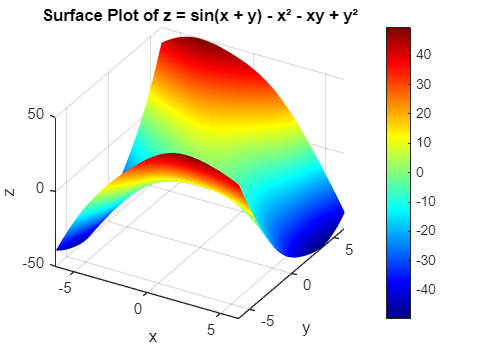


x = linspace(-2*pi, 2*pi, 200);
y = linspace(-2*pi, 2*pi, 200);
[X, Y] = meshgrid(x, y);

Z = sin(X + Y) - X.^2 - X.*Y + Y.^2;

figure;
surf(X, Y, Z, 'EdgeColor', 'none');
colormap('jet');
colorbar;
shading interp;

xlabel('x');
ylabel('y');
zlabel('z');
title('Surface Plot of z = sin(x + y) - x² - xy + y²');
view(30, 35);

## question 4

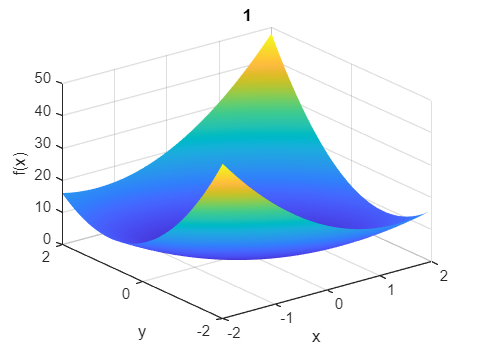

% 1
x = linspace(-2, 2, 100);
y = linspace(-2, 2, 100);
[X, Y] = meshgrid(x, y);
A = [3 2; 2 5];
Z = A(1,1)*X.^2 + 2*A(1,2)*X.*Y + A(2,2)*Y.^2;
figure; surf(X, Y, Z); shading interp; title('1'); xlabel('x'); ylabel('y'); zlabel('f(x)');

eig(A)

ans =     1.7639
    6.2361


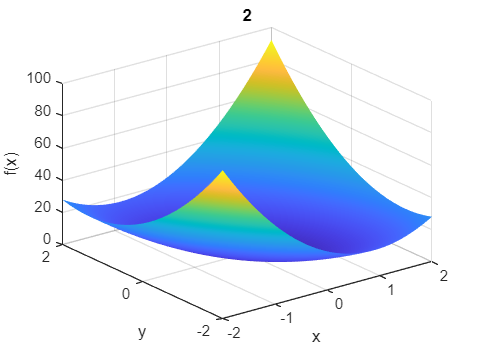


% 2
B = [9 4; 4 6];
Z = B(1,1)*X.^2 + 2*B(1,2)*X.*Y + B(2,2)*Y.^2;
figure; surf(X, Y, Z); shading interp; title('2'); xlabel('x'); ylabel('y'); zlabel('f(x)');

eig(B)

ans =     3.2280
   11.7720


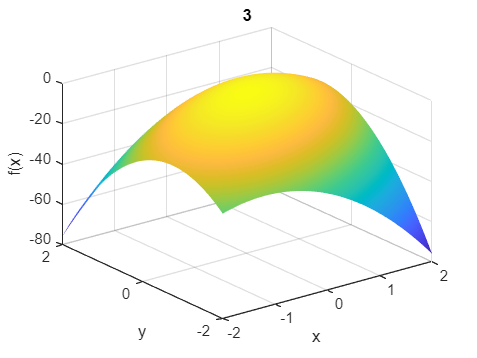


% 3
C = [-5 3; 3 -8];
Z = C(1,1)*X.^2 + 2*C(1,2)*X.*Y + C(2,2)*Y.^2;
figure; surf(X, Y, Z); shading interp; title('3'); xlabel('x'); ylabel('y'); zlabel('f(x)');

eig(C)

ans =    -9.8541
   -3.1459


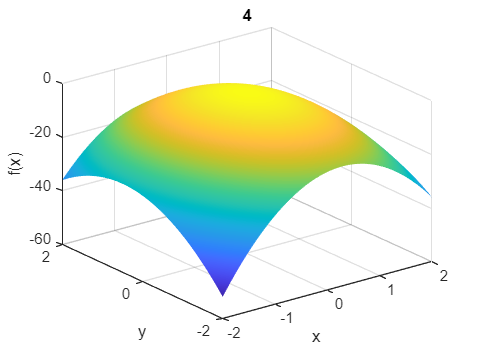


% 4
D = [-7 -1; -1 -4];
Z = D(1,1)*X.^2 + 2*D(1,2)*X.*Y + D(2,2)*Y.^2;
figure; surf(X, Y, Z); shading interp; title('4'); xlabel('x'); ylabel('y'); zlabel('f(x)');

eig(D)

ans =    -7.3028
   -3.6972


## question 5


A = randn(6,2);

S = A' * A;

% a. find eigenvalues
eig(S)

ans =     1.1410
    9.0566


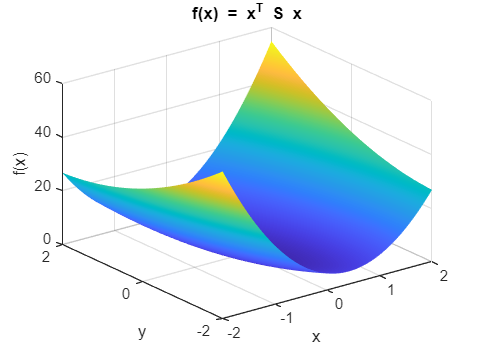


% b. plot f(x) = x^T S x
x = linspace(-2, 2, 100);
y = linspace(-2, 2, 100);
[X, Y] = meshgrid(x, y);
Z = S(1,1)*X.^2 + 2*S(1,2)*X.*Y + S(2,2)*Y.^2;
figure; surf(X, Y, Z); shading interp; title('f(x) = x^T S x'); xlabel('x'); ylabel('y'); zlabel('f(x)');

## question 6

syms x y z

syms requires Symbolic Math Toolbox.

f = 4*x^3*exp(x*y) - y^3*z;
grad_f = gradient(f, [x y z]);
hess_f = hessian(f, [x y z]);
disp('Gradient of f:')
disp(grad_f)
disp('Hessian of f:')
disp(hess_f)





